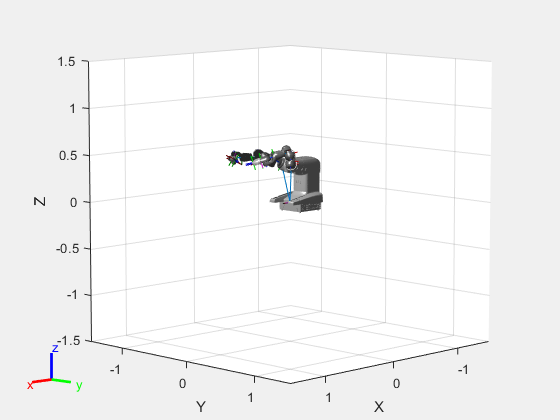

%%Load Robot Visualization and Build Environment
clear

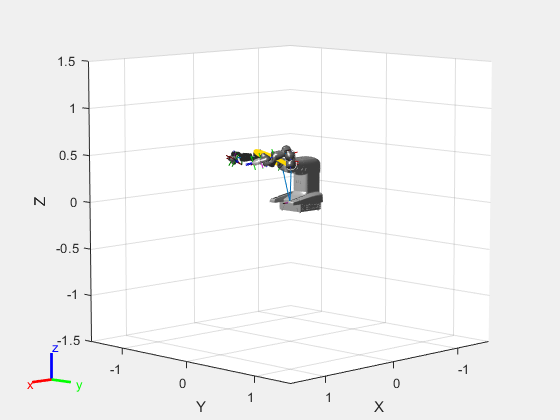

clc
robot = loadrobot('abbYumi', 'Gravity', [0 0 -9.81]);
robot.DataFormat = 'row'; 
iviz = interactiveRigidBodyTree(robot);
ax = gca;
iviz.MarkerBodyName = "gripper_r_base";
iviz.MarkerBodyName = "yumi_link_2_r";
iviz.MarkerControlMethod = "JointControl";
addConfiguration(iviz)
load abbYumiSaveTrajectoryWaypts.mat

removeConfigurations(iviz) % Clear stored configurations

% Start at a valid starting configuration
iviz.Configuration = startingConfig;
addConfiguration(iviz)

% Specify the entire set of waypoints
iviz.StoredConfigurations = [startingConfig, ...
                             graspApproachConfig, ...
                             graspPoseConfig, ...
                             graspDepartConfig, ...
                             placeApproachConfig, ...
                             placeConfig, ...
                             placeDepartConfig, ...
                             startingConfig];
% %Build environment
% % plane = collisionBox(1.5,1.5,0.05);
% % plane.Pose = trvec2tform([0.25 0 -0.025]);
% % show(plane,'Parent', ax);
% % 
% % leftShelf = collisionBox(0.25,0.1,0.2);
% % leftShelf.Pose = trvec2tform([0.3 -.65 0.1]);
% % [~, patchObj] = show(leftShelf,'Parent',ax);
% % patchObj.FaceColor = [0 0 1];
% % 
% % rightShelf = collisionBox(0.25,0.1,0.2);
% % rightShelf.Pose = trvec2tform([0.3 .65 0.1]);
% % [~, patchObj] = show(rightShelf,'Parent',ax);
% % patchObj.FaceColor = [0 0 1];
% % 
% % leftWidget = collisionCylinder(0.01, 0.07);
% % leftWidget.Pose = trvec2tform([0.3 -0.65 0.225]);
% % [~, patchObj] = show(leftWidget,'Parent',ax);
% % patchObj.FaceColor = [1 0 0];
% % 
% % rightWidget = collisionBox(0.03, 0.02, 0.07);
% % rightWidget.Pose = trvec2tform([0.3 0.65 0.225]);
% % [~, patchObj] = show(rightWidget,'Parent',ax);
% % patchObj.FaceColor = [1 0 0];
% % 
% % centerTable = collisionBox(0.5,0.3,0.05);
% % centerTable.Pose = trvec2tform([0.75 0 0.025]);
% % [~, patchObj] = show(centerTable,'Parent',ax);
% % patchObj.FaceColor = [0 1 0];
% 
% %%Interactively Generate Configurations
% iviz.MarkerBodyName = "gripper_r_base";
% iviz.MarkerBodyName = "yumi_link_2_r";
% iviz.MarkerControlMethod = "JointControl";
% %Svae current configuration
% %addConfiguration(iviz)
% 
% %%Define Waypoints for a Trajectory
%  load abbYumiSaveTrajectoryWaypts.mat
%  removeConfigurations(iviz) % Clear stored configurations
% % % Start at a valid starting configuration
%  iviz.Configuration = startingConfig;

%  addConfiguration(iviz)
% % % Specify the entire set of waypoints
%  iviz.StoredConfigurations = [startingConfig, ...
%                              graspApproachConfig, ...
%                              graspPoseConfig, ...
%                              graspDepartConfig, ...
%                              placeApproachConfig, ...
%                              placeConfig, ...
%                              placeDepartConfig, ...
%                              startingConfig];
% % % Gravity Torque
% % 
% % % q = iviz.Configuration';
% % % gtau = gravityTorque(robot,q);
% % %plot(robot.NumBodies,gtau ...
% % %% Generate the Trajectory and Play It Back
% % numSamples = 100*size(iviz.StoredConfigurations, 2) + 1;
% % [q,~,~, tvec] = trapveltraj(iviz.StoredConfigurations,numSamples,'EndTime',2);
% % %Replay the generated trajectory by  a series of joint configurations that move between each waypoint
% % iviz.ShowMarker = false;
% % showFigure(iviz)
% % rateCtrlObj = rateControl(numSamples/(max(tvec) + tvec(2)));
% % for i = 1:numSamples
% %     iviz.Configuration = q(:,i);
% %     waitfor(rateCtrlObj);
% %     gtau = gravityTorque(robot,iviz.Configuration);
% % end
% % plot(i,iviz.Configuration)
% 

## Plan and Execute Task- and Joint-Space Trajectories

% %Create a inverse kinematics object for the robot.
% %ik = inverseKinematics('RigidBodyTree',robot);
% %Set current robot joint configuration
% 
% currentConfiguration = iviz.Configuration;
% 
% %Get number of joints and the end-effector RBT frame 
% numJoints = numel(iviz.Configuration);
% endEffector1 = "gripper_r_base";
% 
% %Specify the trajectory time step and approximate desired tool speed
% timeStep = 0.1; % seconds
% toolSpeed = 0.1; % m/s
% 
% %Set the initial and final end-effector pose
% 
% jointInit = currentConfiguration;
% taskInit = getTransform(robot,jointInit',endEffector1);
% 
% taskFinal = trvec2tform([0.4,0,0.6])*axang2tform([0 1 0 pi]);
% 
% distance = norm(tform2trvec(taskInit)-tform2trvec(taskFinal));
% initTime = 0;
% finalTime = (distance/toolSpeed) - initTime;
% trajTimes = initTime:timeStep:finalTime;
% timeInterval = [trajTimes(1); trajTimes(end)];
% 
% %Generate Joint-Space Trajectory
% iviz.IKSolver.SolverParameters.AllowRandomRestart = false;
% %ik.SolverParameters.AllowRandomRestart = false;
% weights = [1 1 1 1 1 1 ];
% 
% %Calculate the initial and desired joint config using ik.
% %Wrap the values to pi to ensure that interpolation is over a minimal
% %domain
% initialGuess = jointInit;
% %iviz.IKSolver.ConstraintInputs = {'',''}
% %jointFinal= iviz.IKSolver(endEffector1,taskFinal,weights,initialGuess);
% jointFinal = inverseKinematics(endEffector1, taskFinal,weights,initialGuess);

Error using inverseKinematics
Too many output arguments.

% %The continuous joints will be mapped to the interval [-pi,pi], and the
% %other values will remain the same.
% wrappedJointFinal = wrapToPi(jointFinal);
% 
% %A cubic polynomial function to generate an array of evenly-spaced joint
% %configurations. Use a B-spline to generate a smoothe trajectory.
% ctrlpoints = [jointInit',wrappedJointFinal'];
% jointConfigArray = cubicpolytraj(ctrlpoints,timeInterval,trajTimes);
% jointWaypoints = bsplinepolytraj(jointConfigArray,timeInterval,1);
% %
% %[taskWaypoints,taskVelocities] = transformtraj(taskInit,taskFinal,timeInterval,trajTimes); 
% %Control Joint-Space Trajectory
% jsMotionModel = jointSpaceMotionModel('RigidBodyTree',robot,'MotionType','PDControl');
% %Set initial state
% q0 = currentRobotJConfig; 
% qd0 = zeros(size(q0));
% %Simulation of motion
% [tJoint,stateJoint] = ode15s(@(t,state) exampleHelperTimeBasedJointInputs(jsMotionModel,timeInterval,jointConfigArray,t,state),timeInterval,[q0; qd0]);
% % Return to initial configuration
% show(robot,currentRobotJConfig,'PreservePlot',false,'Frames','off');
% 
% for i=1:length(trajTimes)
%     % Current time 
%     tNow= trajTimes(i);
%     % Interpolate simulated joint positions to get configuration at current time
%     configNow = interp1(tJoint,stateJoint(:,1:numJoints),tNow);
%     poseNow = getTransform(robot,configNow,endEffector1);
%     show(robot,configNow,'PreservePlot',false,'Frames','off');
%     plot3(poseNow(1,4),poseNow(2,4),poseNow(3,4),'r.','MarkerSize',20)
%     drawnow;
% end